# INPUT MuRAT3D - Toba

This is an input file for the program Multi-Resolution Attenuation Tomography (MuRAT), version 3. It refers to the following area:

**The working directory is the folder where you downloaded MuRAT: move it anywhere in your system.**

## GENERAL FIELDS

The user needs a data directory containing *.sac* files (beware of the difference between *.sac* and *.SAC*). If you want to use two or three-component recordings, you have to store them  into a single folder, but the three components must be in the exact order **E,N,Z**. For an example see Toba. For this example we will use data in the **sac_Toba** folder. Inside this folder, three-component (*W,N,Z*) seismograms are stored:

Murat.input.dataDirectory           =   'sac_Toba';

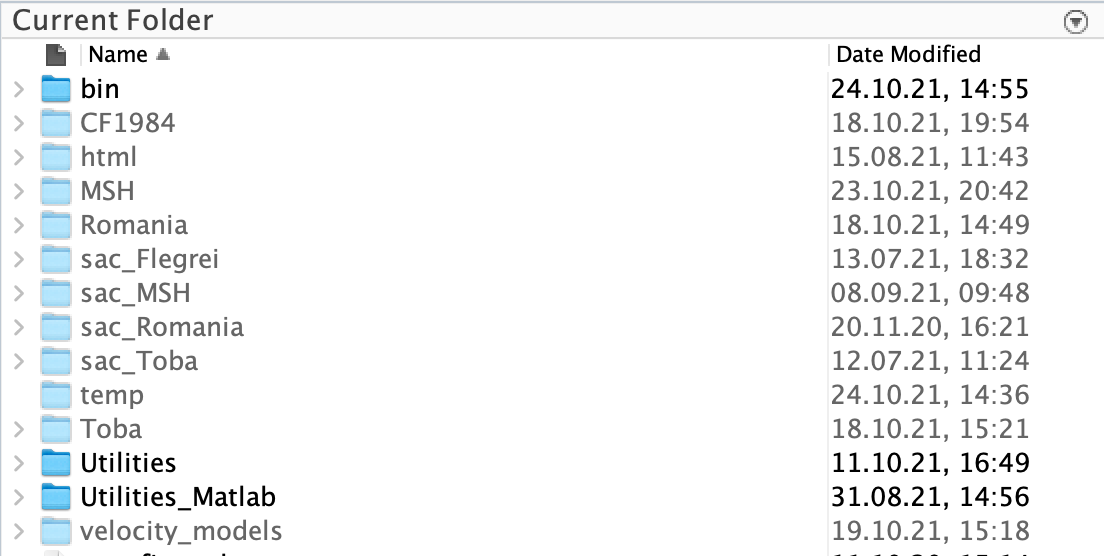

Best practice is to create a new folder to store your results. The code will create this folder inside the working directory. Specify the name of the folder that will store text files and figures, and will appear in your working directory:

Murat.input.label                   =   'Toba';

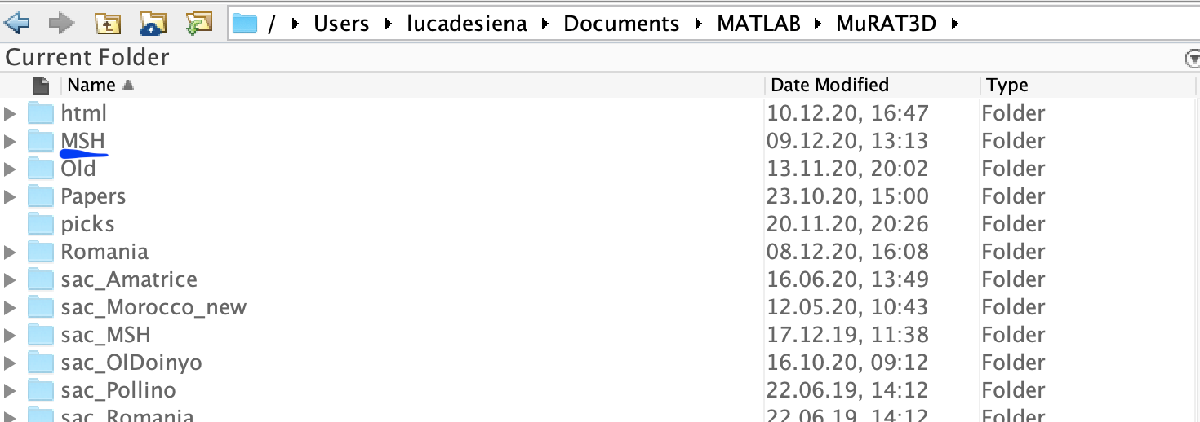

In MuRAT3D you can choose between a sequential or parallelized forward loop. In the parallelized case, just set a number of workers (cores). In this example, we are working with the parallelized code and a computer with 8 cores. Otherwise, set *Murat.input.workers* as empty (**[]**).

Murat.input.workers                 =   8;

## WAVEFORM DATA

Set all the variables required by data processing. This includes data choises, as setting the name of the variables in SAC and all the attributes that are needed for the three kinds of imaging. The routines for loading the files have been mostly created by [Zhigang Peng ](http://geophysics.eas.gatech.edu/people/zpeng/)and co-workers and downloaded from their [Introduction to SAC](http://geophysics.eas.gatech.edu/people/zpeng/Teaching/Sac_Tutorial_2006/) webpage.

MuRAT3D is designed to work with *sac* files only, so it is necessary to set the name of the variable containing their peakings and zero time. Files have to have populated headers. Set the name of the variable containing the origin time, P-wave peaking and S-wave pickings - in this example there is only the mandatory P-wave picking. If you don't have the origin time and S-wave times at hand you can mark them as empty (**[]**):

Murat.input.originTime              =   'o';
Murat.input.PTime                   =   'a';
Murat.input.STime                   =	't0';

Then choose the coherent phase you are analyzing - P-(**2**) or S-(**3**). In our case it is S-wave picking.

Murat.input.POrS                    =	3;

You need to set the central frequencies (Hz) according to your spectrograms. General practice is to vary it across your spectra (see [De Siena et al. 2016, EPSL](https://www.sciencedirect.com/science/article/abs/pii/S0012821X16300437)) for absorption and scattering mapping or focus on a given frequency ([De Siena et al. 2014, JGR](https://agupubs.onlinelibrary.wiley.com/doi/abs/10.1002/2014JB011372)) for direct-wave attenuation imaging. Here, they cover the interval [1.5-24] Hz.

Murat.input.centralFrequency        =	[1.5 3];

Here we use three components:

Murat.input.components              =	3;

## PEAK DELAY

Scattering (peak delay) measurements rely on the existence of coherent waves. Peak delay is a standard measurements of forward scattering in regional scale-mapping since [Takahashi et al. 2007, GJI](https://academic.oup.com/gji/article/168/1/90/581022?login=true). Here, we approach the problem by  adding a ray-tracing strategy to the system, assuming that the sensitivity follows the seismic ray. Also, we bring it to 3D and apply it to P-waves (see [De Siena et al. 2016, EPSL](https://www.sciencedirect.com/science/article/abs/pii/S0012821X16300437)).

To do so we need to set a minimum peak delay (*s*) considering scattering in the area and frequency. If using P wave this is crucial, as they can be sometimes more energetic than S-waves, biasing our measurements. We also need to set the maximum peack-delay (*s*) to avoid picking surface waves.

Murat.input.minimumPeakDelay        =	0.1;
Murat.input.maximumPeakDelay        =	10;

## DIRECT WAVE ATTENUATION

Total attenuation (inverse Q) measurements also relies on the existence of coherent waves. Total attenuation with the coda-normalization method is today astandard in volcano tomography ([Del Pezzo et al. 2006, PEPI](https://www.sciencedirect.com/science/article/pii/S0031920106001282), [De Siena et al. 2010, JGR](https://agupubs.onlinelibrary.wiley.com/doi/full/10.1029/2009JB006938); [De Siena et al. 2014, JGR](https://agupubs.onlinelibrary.wiley.com/doi/full/10.1002/2014JB011372), [Prudencio et al. 2015](https://link.springer.com/article/10.1007/s10712-015-9322-6), [Prudencio & Manga, 2020](https://academic.oup.com/gji/article-abstract/220/3/1677/5650518).

The method relies on the measurements of both direct and coda wave energy. Therefore we need to set the spectral energy decay of the coda wavefield. The spectral decay has to be set for prdominance of 2D surface  (0.5), diffusive (1.5) or body waves (2). Here it is it is the first case:

Murat.input.spectralDecay           =	0.5;

Then we set the length of the window used to measure  direct-wave energy, trying to smooth radiation pattern effects. The code uses the lame length to measure noise energy. Discussions on the topic can be found in [De Siena et al. 2009, PEPI](https://www.sciencedirect.com/science/article/pii/S0031920108003178?casa_token=FBQxspuFhPcAAAAA:P1a7DnDvjJpf9HVV1JzKsX-fzONnmmuUYMOZhAKOdRd_5Al7EHb5AydQAhjAwiIyBhMOq1xKNA) and [De Siena et al. 2010, JGR](https://agupubs.onlinelibrary.wiley.com/doi/abs/10.1029/2009JB006938), but the choise is as usual dependent on data:

Murat.input.bodyWindow              =	1;

We also need the start of the window used to measure noise a few seconds after the start of the recording (in seconds).

Murat.input.startNoise              =	3;

The coda-to-noise energy ratio is used by the weighted inversion. Here you set the minimum accepted energy ratio.

Murat.input.tresholdNoise           =	3;

## CODA ATTENUATION

Coda attenuation (inverse Qc) is measured from the decay of the coda with lapse time from the origin time of the earthquake, and requires energetic scattering. Qc is a well know parameter for assesing tectonic structures ([Sato et al. 2012, Springer](https://link.springer.com/book/10.1007/978-3-642-23029-5)). In recent years it has been used as an imaging attribute at the regional ([Calvet et al. 2013, Tectonophysics](https://www.sciencedirect.com/science/article/abs/pii/S0040195113005490); [Borleanu et al. 2017, Tectonophysics](https://www.sciencedirect.com/science/article/pii/S0040195117301476)), fault ([Napolitano et al. 2020](https://www.sciencedirect.com/science/article/pii/S1674987119301999); [Sketsiou et al. 2020, PEPI](https://www.sciencedirect.com/science/article/pii/S0031920119302122)) and, especially, volcanic scales ([Prudencio et al. 2013a, GJI](https://academic.oup.com/gji/article/195/3/1957/2874185?login=true); [Prudencio et al. 2013b GJI](https://academic.oup.com/gji/article/195/3/1942/626933);  [De Siena et al. 2016, EPSL](https://www.sciencedirect.com/science/article/abs/pii/S0012821X16300437); [De Siena et al. 2017, GRL](https://agupubs.onlinelibrary.wiley.com/doi/abs/10.1002/2017GL072507); [Gabrielli et al. 2020, GJI](https://academic.oup.com/gji/article-abstract/222/1/169/5814316)).

### Lapse times and sensitivity kernels

In MuRAT3D, we use the full 3D computational kernels devised by [Del Pezzo et al. 2018, Geosciences](https://www.mdpi.com/2076-3263/8/5/175) in the inversion approach proposed first by [De Siena et al. 2017, GRL](https://agupubs.onlinelibrary.wiley.com/doi/abs/10.1002/2017GL072507).

Here you choose the start of the window used to measure coda wave energy and model kernels. The starting time of the coda window can be set directly in seconds ('**Constant**'), from the envelope peak ('**Peak**'), or depending on the P- or S-wave travel time, for example twice the S-wave travel time ('**Travel**'). If the chosen method is **Constant**, set start and length of the window.

Murat.input.lapseTimeMethod         =   'Constant';

If the chosen method is **Constant**, set the start of the window in seconds after the origin time. It it is **Peak**, set it to **[]**. If it is **Travel **select *Murat.input.startLapseTime* as the moltiplicative factor of the pahase you are using (e.g., **2** or **3**). Avoid this method if you do not know the S-wave time.

Murat.input.startLapseTime          =   60;

Finally set the length of the coda window in seconds. The true lapse time at which we calculate the kernels is half of the window. The window is also used (after normalizing for its length) in the coda normalization method.

Murat.input.codaWindow              =   20;

The **MLTWA** is the standard method to find the average parameters necessary to calculate the kernels. It provides albedo and extinction length:

Murat.input.albedo                  =   0.5;
Murat.input.extinctionLength        =   0.02;

As the kernels are computational intensive and require a full matrix of nodes to avoid singularities, we also use a computational factor to reduce the computational time. This number divides the input grid, meaning that higher numbers give more precise results at the expene of computational time. Minimum is **1**. A figure will output the kernel in this grid.

Murat.input.kernelTreshold          =	1;

### Measurement of Qc

MuRAT3D  implements either a linearised approach or a grid search approach to measure Qc. The linearised approach is the standard proposed first by Aki (e.g., [Havskov et al. 2016, BSSA](https://www.researchgate.net/publication/303510878_Coda_Q_in_Different_Tectonic_Areas_Influence_of_Processing_Parameters)) to best fit Qc after taking the logarithm of the energy. The uncertainties are derived from the simple minimum R-squared (fitTresholdLinear) and needs to be defined by a number between 0 and 1. It is advisable to set a minimum of 0.1.

The non linear approach models energy data measured on one-second windows across the envelope and minimizes the difference between data and model with a 1D grid search algorithm ([Napolitano et al. 2020](https://www.sciencedirect.com/science/article/pii/S1674987119301999)).  Uncertainties are given by the experimental probability density function of the misfit. In both cases, uncertainties play as a weight in the final inversion. In the second case, leave the fitTresholdLinear =** []**.

The user needs to choose between the two options **'Linearized'** and **'NonLinear':**

Murat.input.QcMeasurement           =   'Linearized';
Murat.input.fitTresholdLinear       =	0.1;

## GEOMETRY AND VELOCITY

This section sets the details of the inversion grid. In MuRAT3D the coordinates of the model are in lat/lon, then they get converted in km. The vertical is in altitude above sea level. The velocity model can be 1D or 3D - if 3D all poins must be given in lat/long formats.

You start by setting the origin and end points of your inversion grid.

Murat.input.origin                  =   [0 96 2000];
Murat.input.end                     =   [4 100 -30000];

Then you need to set the number of nodes in the three directions. This is obviously dependent on the scale of your area. You will be playing alot with this to test your resolution.

Murat.input.gridLat                 =   17;
Murat.input.gridLong                =   17;
Murat.input.gridZ                   =   11;

### Velocity model

With this version of the code you are always using an underlying velocity model: the 3D is either unavailable(***0***) or a vailable (***1***) velocity model.  For the 1D case MuRAT provides you *iasp91.txt*, the standard [IASPEI velocity model](https://academic.oup.com/gji/article/105/2/429/705789) and expands it to a false 3D. However, a standard crustal model is generally available everywhere on the Earth, so use that - but change it to the same format as the file provided, first column is depth, second is distance from the centre of the Earth, then third and fourth are P- and S-wave velocity. Store the file in the folder **velocity_models**. Here, we use *iasp91*:

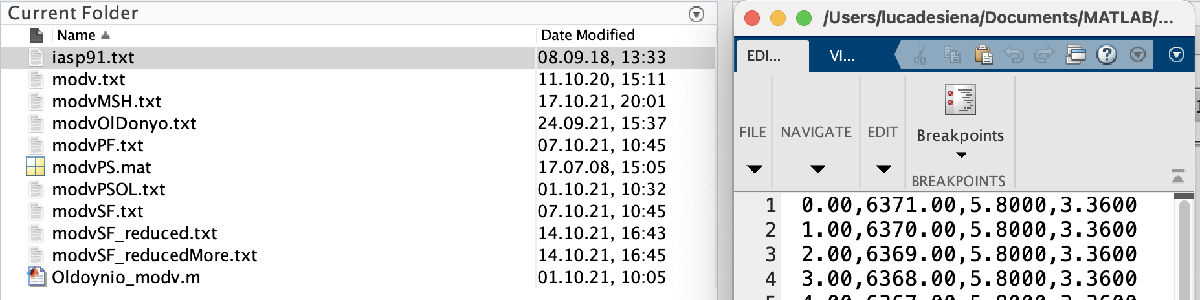

So we set:

Murat.input.availableVelocity       =	0;
Murat.input.namev                   =   'iasp91.txt';

Even if we set the velocity model we still need the average crustal velocities if you have no info of origin time. It is highly recommended you have the origin in the haeder, at variables **'o'**!

Murat.input.averageVelocityP        =   7;
Murat.input.averageVelocityS        =   4;

## INVERSION AND PLOTTING

### Inversion

The code implements either a standard Tikhonov inversion based on singular value decomposition (**'Tikhonov'**) and an iterative conjugate graduate least square inversion minimizing both model norm and Laplacian (**'Iterative'**). For the first, we rely on the [regtools Matlab suite](https://de.mathworks.com/matlabcentral/fileexchange/52-regtools) from Per Christian Hansen. The second uses the [IR TOOLS for iterative regularization](https://link.springer.com/article/10.1007/s11075-018-0570-7). Copies of both packages are linked to MURAT3.

Murat.input.inversionMethod         =   'Iterative';

As you need to select the damping you can choose to output the L curves between residual and norm length ([Aster et al. 2013](https://www.sciencedirect.com/book/9780123850485/parameter-estimation-and-inverse-problems) - case **'Tikhonov'**) or the cost functions (case **'Iterative**'). Set either ***1*** or ***0***. In the latter case, set the damping for both Qc and Q inversions. You will likely test many different damping parameters and likely want to avoid seeing the same figure again, so you can just declare the damping for Qc and Q after looking at the figures. Remember doing it for each frequency.

Murat.input.lCurve                  =   0;
Murat.input.lCurveQc                =   [0.1 0.05];
Murat.input.lCurveQ                 =   [10 1];

### Testing

A great reference for the best sort of testing is [Rawlinson & Spakman, 2016](https://academic.oup.com/gji/article/205/2/1221/692880?login=true). If you want to test you results you need to create a checkerboard. The size of the checks can be  twice (*2*) or four times (*4*) node spacing.

Murat.input.sizeCheck               =   2;

with each cell having alternating values of attenuation:

Murat.input.highCheck               =   0.02;
Murat.input.lowCheck                =   0.001;

In MuRAT3D you set the origin ad end locations of the spike as:

Murat.input.spikeLocationOrigin     =   [2 98.5 -10000];
Murat.input.spikeLocationEnd        =   [4 99.5 -20000];

while its value is:

Murat.input.spikeValue              =   0.02;

### Plotting

The last inputs are your preferred figure format - 'jpeg' (fast) or 'tiff' (for publication):

Murat.input.format                  =   'jpeg';

and the sections where you will slice your plots. MuRAT3D now saves everything in Paraview format (.VTK) but some checks in Matlab can be useful. You will see all of your figures on three sections cutting the models WE (degrees), SN (degrees), and horizontally (meters or km) at:

Murat.input.sections                =	[2.5 99 -10000];

All these sections are saved in the Label folder.